% showing the influcence of control parameters

% build a 2nd order system
G = tf(2,[6 5 1])

G =
 
         2
  ---------------
  6 s^2 + 5 s + 1
 
Continuous-time transfer function.



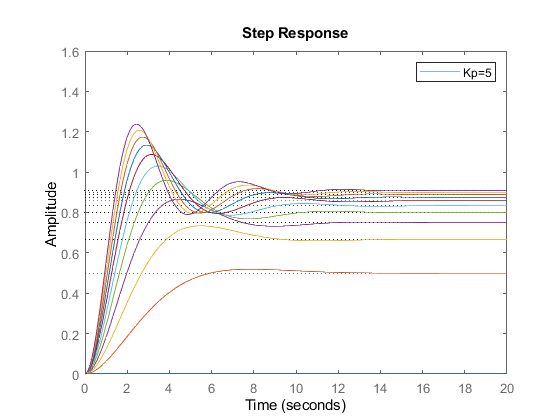

% P control
for Kp = 0: 0.5: 5
     G1 = Kp;                   % P
     sys = feedback(G1 * G, 1); % feedbacj
     step(sys);                 % step response
  
     axis([0 20 0 1.6]);
     figure(1);hold on
     legend(['Kp=' num2str(Kp)])
     pause(0.01);
end

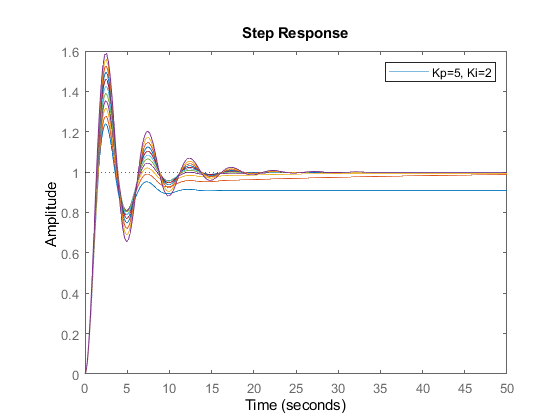

pause
% PI control
Kp = 5;
 for Ki = 0: 0.2: 2
     G1 = tf([Kp Ki], [1 0]);    % PI
     sys = feedback(G1 * G, 1);  % feedback
     figure(20); hold on
     step(sys);                  % step response
  
     axis([0 50 0 1.6]);
     legend(['Kp=' num2str(Kp) ', Ki=' num2str(Ki)])
     pause(0.01);
 end

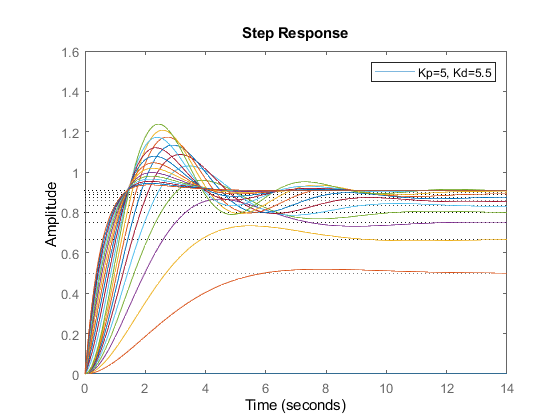

 pause
% PD control
 Kp = 5;
 for Kd = 0: 0.5: 5.5
     G1 = tf([Kd Kp], [0 1]);   % PD
     sys = feedback(G1 * G, 1); % feedback
     figure(3);hold on
     step(sys);                 % step
  
     axis([0 14 0 1.6]);
     legend(['Kp=' num2str(Kp) ', Kd=' num2str(Kd)])
     pause(0.01);
 end

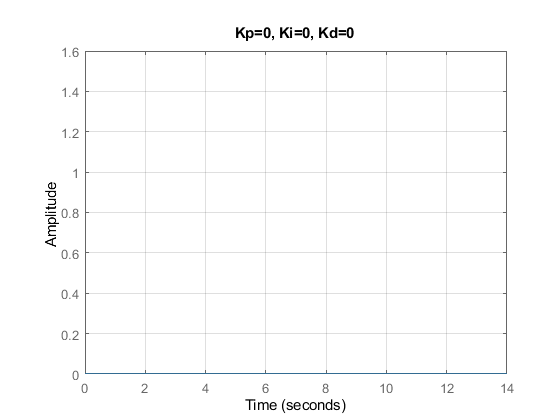

 pause
 figure(4);grid on
 Ki=0;Kd=0;
 for Kp = 0:0.5: 5;
    G1 = tf([Kd, Kp, Ki], [1,0]); % PID
    sys = feedback(G1 * G, 1);    % feedback
    step(sys);grid                    % step
    title(['Kp=' num2str(Kp) ', Ki=' num2str(Ki) ', Kd=' num2str(Kd)])
    axis([0 14 0 1.6]);
    pause(0.01);
 end

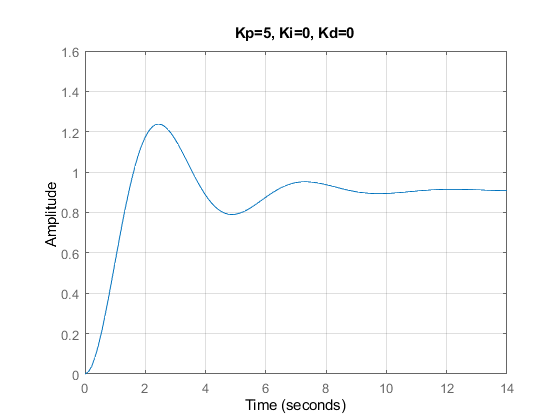

 pause

 for Ki=0:0.1: 1;
    G1 = tf([Kd, Kp, Ki], [1,0]); % PID
    sys = feedback(G1 * G, 1);    % feedback
    step(sys);grid                    % step
    title(['Kp=' num2str(Kp) ', Ki=' num2str(Ki) ', Kd=' num2str(Kd)])
    axis([0 14 0 1.6]);
    pause(0.01);
 end
 pause 
 for Kd=0:0.5:5.5;
    G1 = tf([Kd, Kp, Ki], [1,0]); % PID
    sys = feedback(G1 * G, 1);    % feedback
    step(sys);grid                   % step
    title(['Kp=' num2str(Kp) ', Ki=' num2str(Ki) ', Kd=' num2str(Kd)])
    axis([0 14 0 1.6]);
    pause(0.01);
 end